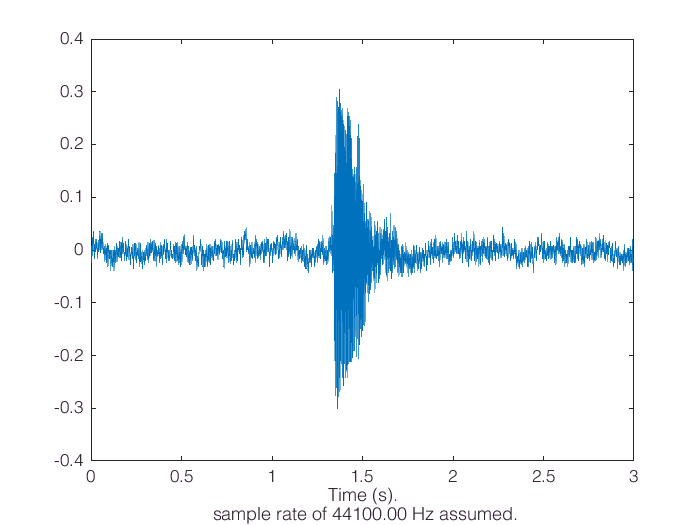

clear
load('dataset_1.mat')
data_1 = [];
data_2 = [];
data_3 = [];
trial_1_filtered = [];
clean_1 = [];
clean_2 = [];
clean_3 = [];

clf
make_time_plot(trial_1(:,6),Fs)

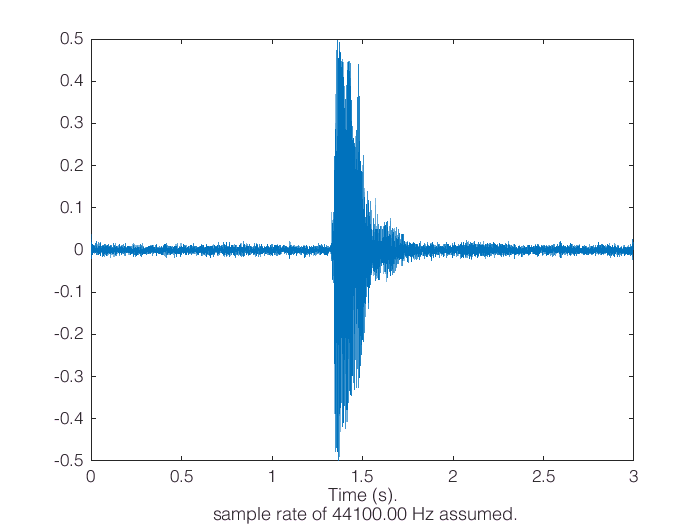

sound(trial_1(:,3),Fs);
filtered = filter_speech(trial_1(:,6),Fs);
make_time_plot(filtered, Fs)

% Filter Audio
for i = 1:size(trial_1,2)
    trial_1_filtered = [trial_1_filtered filter_speech(trial_1(:,i),Fs)];
end

sound(trial_1_filtered(:,3),Fs);

% Equalize the length of each sample

for i = 1:size(trial_1,2)
    j = 1;
    temp = trial_1_filtered(:,i);
    while j < size(temp,1)
        if(temp(j) > 0.1)
            break;
        else
            j = j+1;
        end
    end
    low = round(j-0.1*Fs);
    if low < 0
        low = 1;
    end
    high = low+0.5*Fs;
    
    if high > size(temp,1)
        high = size(temp,1)-1
        low = high-0.6*Fs
    end
    clean_1 = [clean_1 temp(low:high)];
end

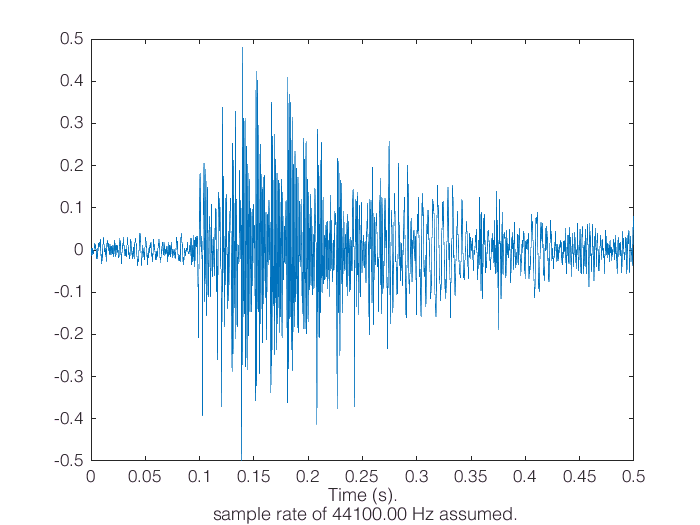

clf
make_time_plot(clean_1(:,16),Fs)


sound(clean_1(:,16),Fs);


% Convert sound to frequency domain
for i = 1:size(trial_1, 2)
    data_1 = [data_1 fft(clean_1(:,i))];
end

% Filter data
% for i = 1:size(trial_1,2)
%     data_1 = [data_1 trial_1(:,i)];    % TODO replace with filtering function call
%     data_2 = [data_2 trial_2(:,i)];
%     data_3 = [data_3 trial_3(:,i)];
% end


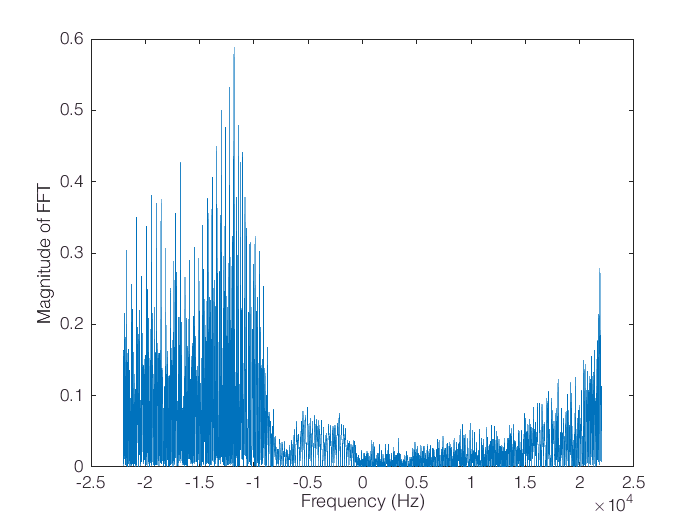

clf
make_freq_plot(data_1(:,2),Fs)

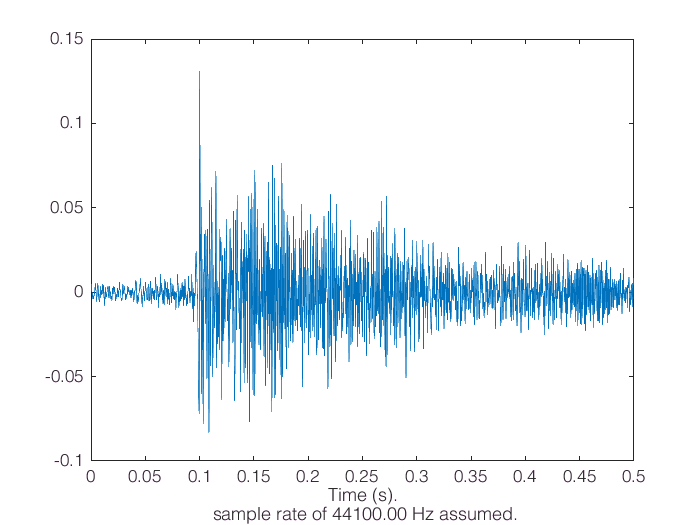


% Calculate mean voice of each dataset
mean1 = mean(data_1,2);



% Convert back to time domain
mean1 = ifft(mean1);

clf
make_time_plot(mean1,Fs)


sound(mean1,Fs)